# Visual Art with MATLAB

This MATLAB Script performs an algorithmic image transformation inspired by a [visual art which demonstrated the transformation using a pasta cutter](https://www.youtube.com/watch?v=f1fXCRtSUWU). 

Import the picture file and visualize it in MATLAB

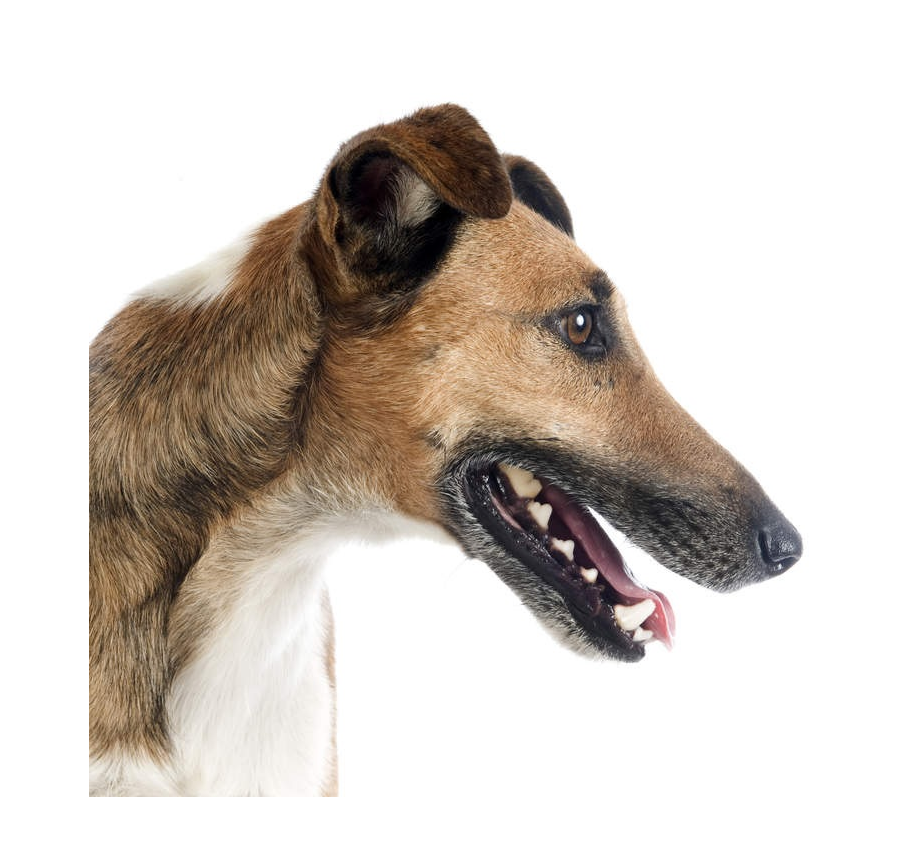

I = imread('dog.jpg');
imshow(I)

Convert the image from a 3D color image into a 2D greyscale image and visualize the result.

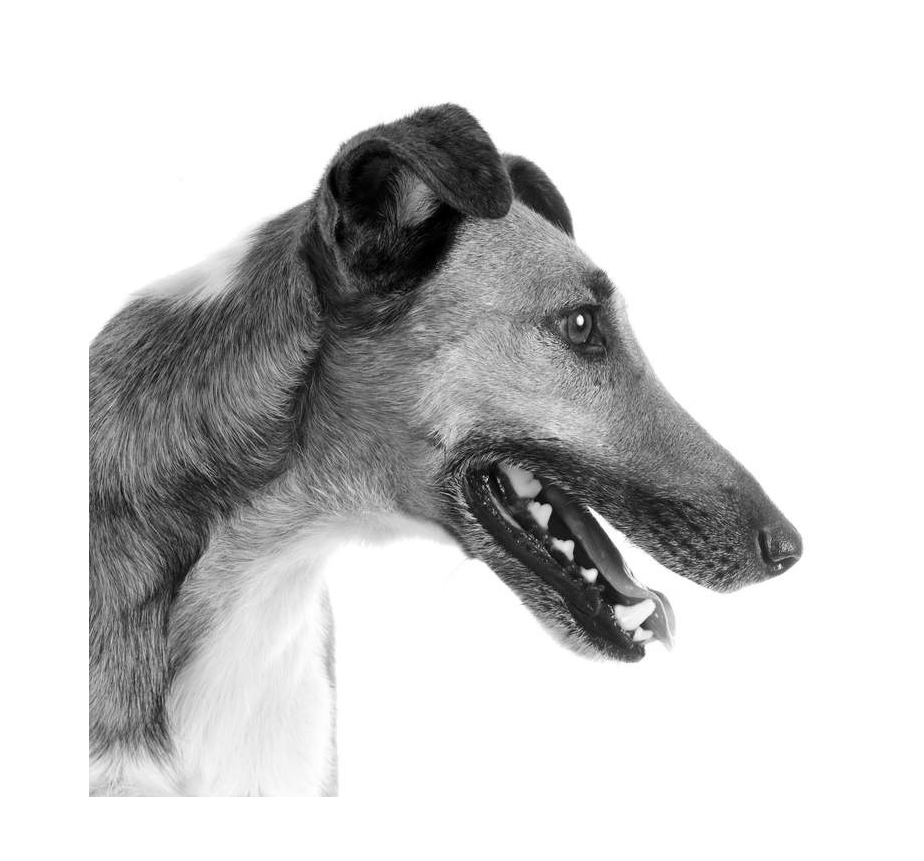

Ig = rgb2gray(I);
Igr = imresize(Ig, [768 744]);
imshow(Igr)

First shred and then reassemble the image to create two dogs. Finally visualize the result.

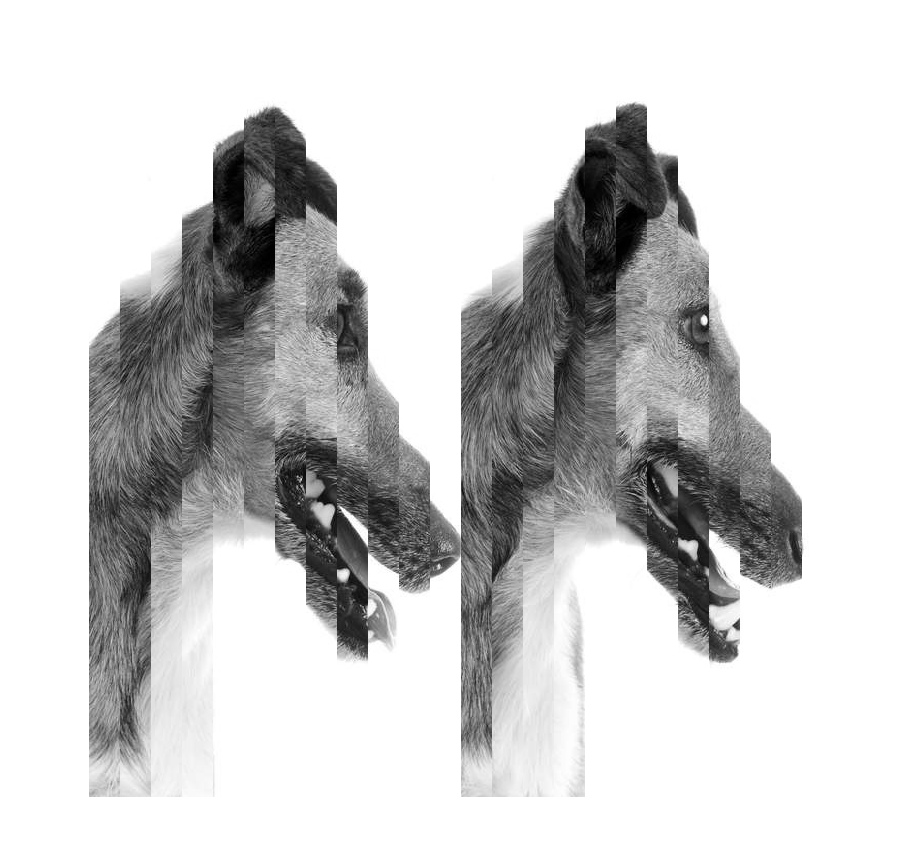

Igshr1 = shredImage(Igr);
Igout1 = assembleImage(Igshr1);
imshow(Igout1)

Shred, reassemble and visualize the image from the previous step

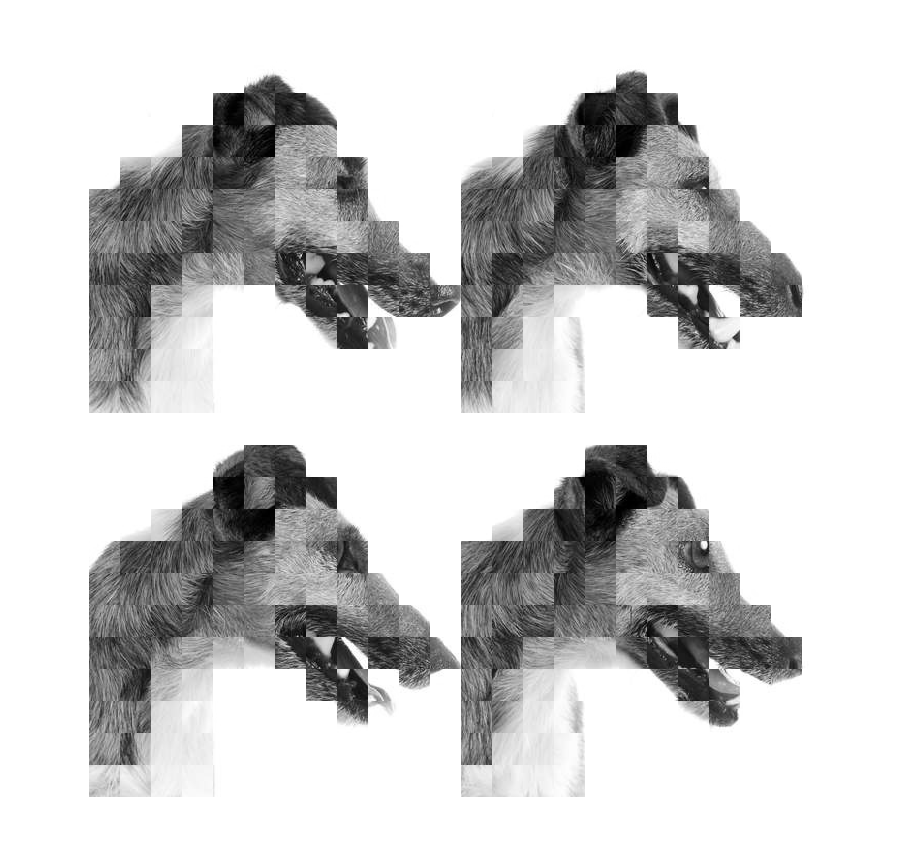

Igshr2 = shredImage(transpose(Igout1));
Igout2 = assembleImage(Igshr2);
Igout2 = transpose(Igout2);
imshow(Igout2)

Function to shred image into 24 parts

function Igsliced = shredImage(I)
    [Il, Iw] = size(I);
    dl = 24;
    sl = Iw/dl;
    Igsliced = zeros(Il,sl,dl,'uint8');
    sla = 1:sl:Iw;
    for i=1:1:dl
        Igsliced(:,1:sl,i) = I(:, sla(i):sla(i)+sl-1);
    end
end 

Function to assemble shreded images

function Igasm = assembleImage(Igsliced)
    [Il, Iw] = size(Igsliced);
    dl = 24;
    Igasmodd = Igsliced(:,:,1:2:dl);
    Igasmeven = Igsliced(:,:,2:2:dl);
    Igasmodd2d = reshape(Igasmodd, [Il,Iw/2]);
    Igasmeven2d = reshape(Igasmeven, [Il,Iw/2]);
    Igasm = cat (2, Igasmodd2d, Igasmeven2d);
end 